clear all;
fs = 1.0e4;
t= -8:1/fs:8;
beta = 50;
signal = sinc(beta.*t)';
plot(t, signal)

grid on


R = green(0,500,5000,500, signal, t);
plot(t,R)

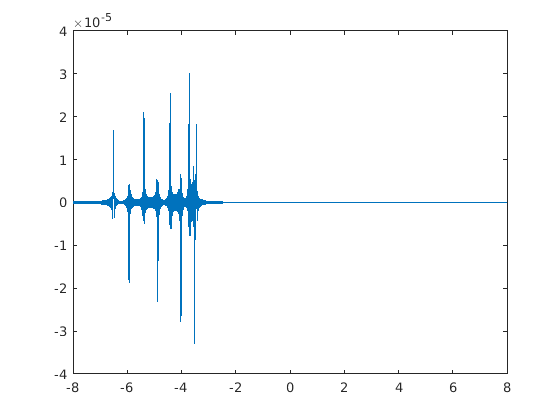

new_s = flip(R);
plot(t,new_s)

new_x = green(5000,500,0,500,new_s,t);
plot(t,new_x)

all_zs = [200,250,300,350,400,450,500,550,600,650,700,750,800]

all_zs =    200   250   300   350   400   450   500   550   600   650   700   750   800


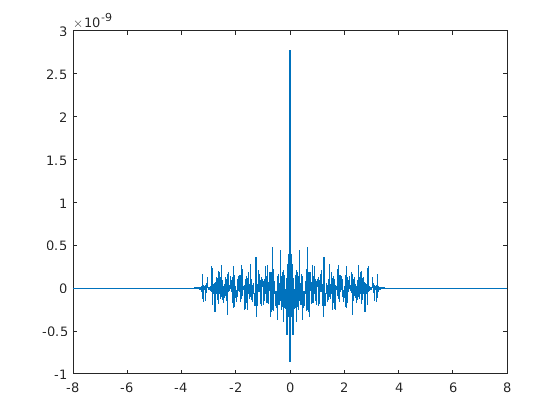

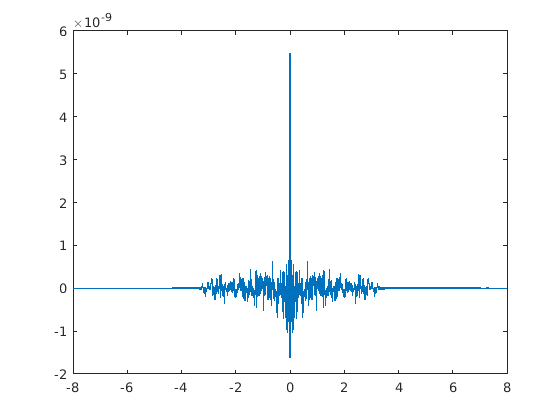

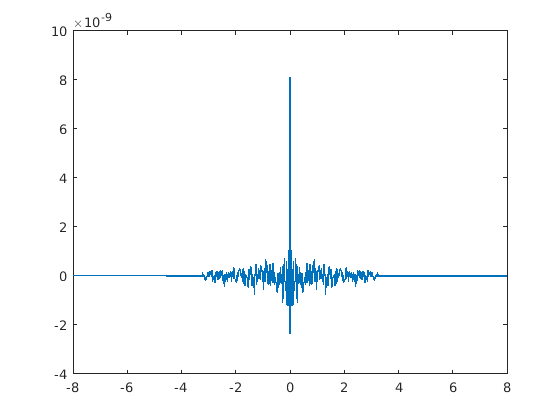

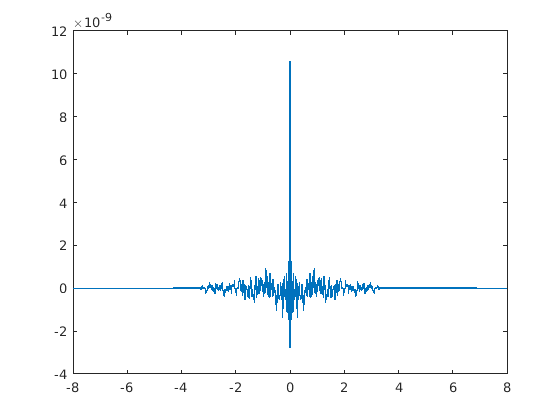

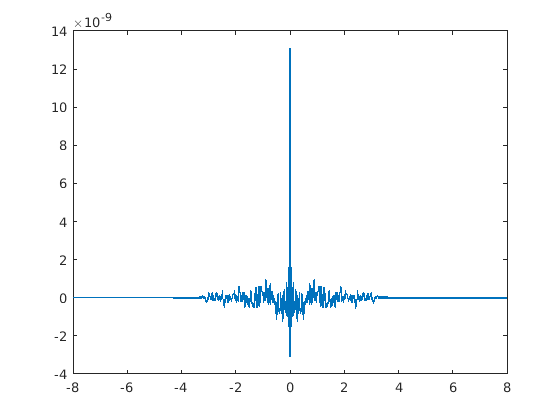

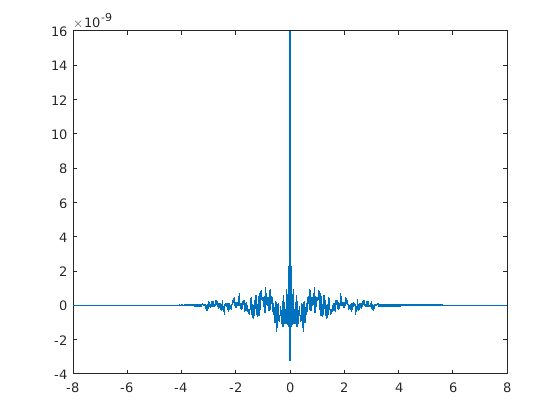

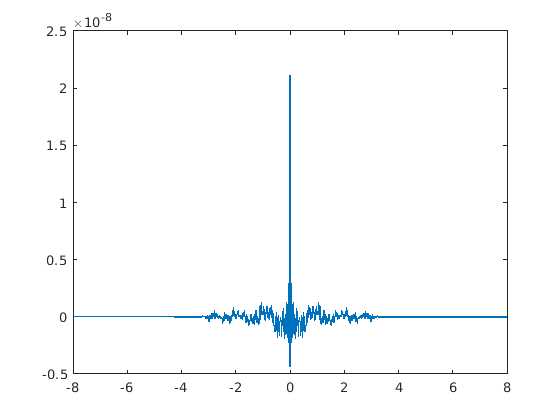

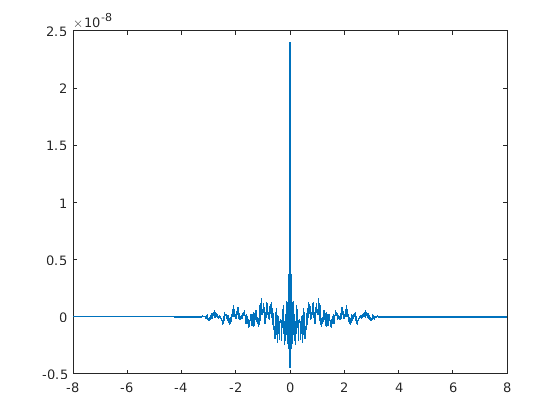

all_R = [];
all_x = zeros(160001,1);
for z=all_zs 
    R = green(0,500,5000,z, signal, t);
    %figure()
    %plot(R)
    R = flip(R);
    new_x = green(5000,z,0,500,R,t);
    all_x = all_x + new_x;
    %figure()
    %plot(t,all_x)
    all_R = horzcat(all_R,R);
end

all_x_coor = -400:15:400;
all_y_coor = 200:15:800;

energy_values = zeros(size(all_x_coor, 2),size(all_y_coor, 2));
ii = 0;
for i = all_x_coor
    ii = ii+1;
    jj= 0;
    i
    for j=all_y_coor
        jj = jj+1;
        
        all_zs =  [200,300,400,500,600,700,800];
        all_R = [];
        all_x = zeros(160001,1);
        for z=all_zs 
            R = green(0,500,5000,z, signal, t);
           
            R = flip(R);
            new_x = green(5000,z,i,j,R,t);
            all_x = all_x + new_x;
            
            %all_R = horzcat(all_R,R);
        end
        energy_x = all_x.^2;
        energy_values(ii, jj) = sum(sum(energy_x));
    end
end

i = -400

i = -385

i = -370

i = -355

i = -340

i = -325

i = -310

i = -295

i = -280

i = -265

i = -250

i = -235

i = -220

i = -205

i = -190

i = -175

i = -160

i = -145

i = -130

i = -115

i = -100

i = -85

i = -70

i = -55

i = -40

i = -25

i = -10

i = 5

i = 20

i = 35

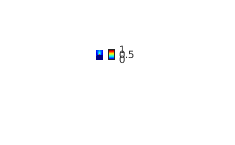

imshow(energy_values/max(max(energy_values)))
colormap(jet(256));
colorbar;

function R = green(x, z,xs, zs,signal, t)
h = 1000;
xs = xs;
zs = zs;
x = x;
z = z;
c = 1450;

fs = 1.0e4;
beta = 50;
r0 = sqrt((x-xs)^2 + (z-zs)^2);
this_signal = delayseq(signal,r0/c,fs);
R = this_signal/(4*pi*r0);

for j = -8:8
    if j ==0
        continue
    end
    if rem(j,2)==0
       r = sqrt((x-xs)^2 + (z-zs+j*h)^2);
       eps = 1;
    else
       r = sqrt((x-xs)^2 + (z+zs-(j+1)*h)^2);
       eps = -1;
    end
    this_signal = delayseq(signal,r/c,fs);
    R = R+(eps/(4*pi*r) *this_signal);
end

end
